X=exp9{:,2:5};
X=zscore(X);
[coeff,score,latent,tsquared,explained,mu] = pca(X);




% variance is latent and is explained
la=latent./sum(latent)*100

la =    92.4616
    5.3016
    1.7185
    0.5183


explained

explained =    92.4616
    5.3016
    1.7185
    0.5183



% manual transform
sc=X*coeff

sc =     2.8271    5.6413   -0.6643   -0.0377
    2.7960    5.1452   -0.8463    0.0609
    2.6215    5.1774   -0.6181   -0.0194
    2.7649    5.0036   -0.6051   -0.1147
    2.7828    5.6486   -0.5465   -0.1018
    3.2314    6.0625   -0.4684   -0.0659
    2.6905    5.2326   -0.3785   -0.0888
    2.8849    5.4851   -0.6586   -0.0850
    2.6234    4.7439   -0.6154   -0.0653
    2.8375    5.2080   -0.8343   -0.0946


% the transformed
score

score =    -2.6842    0.3266   -0.0215    0.0010
   -2.7154   -0.1696   -0.2035    0.0996
   -2.8898   -0.1373    0.0247    0.0193
   -2.7464   -0.3111    0.0377   -0.0760
   -2.7286    0.3339    0.0962   -0.0631
   -2.2799    0.7478    0.1743   -0.0271
   -2.8209   -0.0821    0.2643   -0.0501
   -2.6265    0.1704   -0.0158   -0.0463
   -2.8880   -0.5708    0.0273   -0.0266
   -2.6738   -0.1067   -0.1915   -0.0559


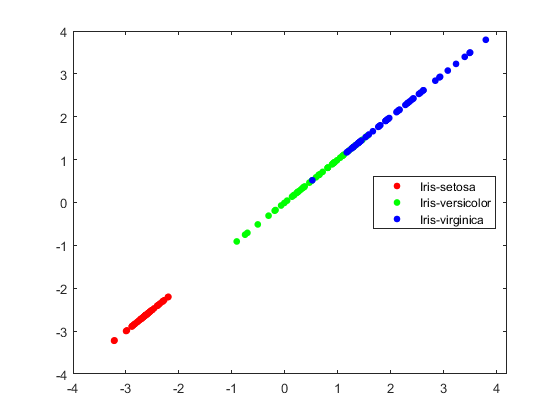

gscatter(score(:,1),score(:,1),exp9.Species)

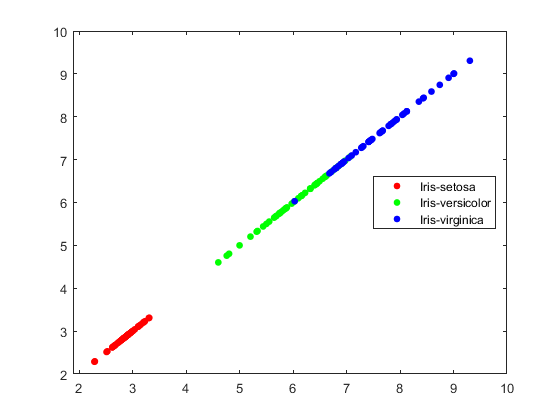

gscatter(sc(:,1),sc(:,1),exp9.Species)

coeff

coeff =     0.3616    0.6565   -0.5810    0.3173
   -0.0823    0.7297    0.5964   -0.3241
    0.8566   -0.1758    0.0725   -0.4797
    0.3588   -0.0747    0.5491    0.7511


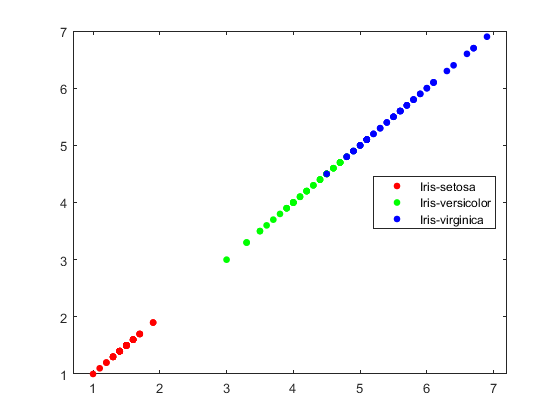

gscatter(exp9.PetalLengthCm,exp9.PetalLengthCm,exp9.Species)